# Estructuras datos: Matrices

La estructura de datos más básica de MATLAB es la matriz. Una matriz es un arreglo rectangular bidimensional de elementos de datos dispuestos en filas y columnas. Los elementos pueden ser números, valores lógicos (verdadero o falso), fechas y horas, cadenas o algún otro tipo de datos de MATLAB.

De forma general se puede pensar que casi todo dentro de MATLAB es una matriz, incluso un solo número se almacena como una matriz.

clear
d = 9.81;
l = true;
s = "Isacc";
% c = 'Isacc';
whos

  Name      Size            Bytes  Class      Attributes

  d         1x1                 8  double               
  l         1x1                 1  logical              
  s         1x1               150  string               



#### Observación

Un arreglo (**array** en inglés) y una matriz no son lo mismo. Un arreglo es una colección o grupo de objetos (datos, variables, etc.), mientras que **una matriz es un tipo de arreglo**, más específicamente es un arreglo homogéneo porque únicamente puede contener elementos del mismo tipo, además que una matriz es bidimensional: sólo tiene filas y columnas. Un arreglo no necesariamente es bidimensional.

## Diferencia entre escalar, vector y matriz

Existen 3 conceptos dentro de MATLAB que se debe saber diferenciar bien cuando se trabajan con matrices:

- **Escalar**: matriz de dimensiones $1\times 1$.

- **Vector**: matriz de dimensiones $1\times m$ o $n\times 1$.

- **Matriz**: agrupación de filas y columnas. Es de dimensiones $m\times n$.

### Escalar

Como se mencionó, un escalar posee las dimensiones $1\times 1$.

whos d

  Name      Size            Bytes  Class     Attributes

  d         1x1                 8  double              



### Vector

Un vector puede ser de dos tipos: **vector fila** ($1\times m$) o **vector columna** ($n\times 1$). La característica que destaca de cada tipo de vector es que posee o bien una sola fila o bien una sola columna.

Ahora que vamos a definir nuestra primera matriz, es importante conocer lo siguiente:

- **Una matriz se define con corchetes** `[]`

- Para separar las columnas se utiliza la coma `,`

- Para separar las filas se utiliza el punto y coma `;`

clear

% Vector fila.
vectorFila = [1,2,3,4,5]

vectorFila =      1     2     3     4     5


% Vector columna.
vectorColumna = [1;2;3;4;5]

vectorColumna =      1
     2
     3
     4
     5


whos

  Name               Size            Bytes  Class     Attributes

  vectorColumna      5x1                40  double              
  vectorFila         1x5                40  double              



### Matriz

Para crear una matriz utilizamos tanto `;` como `,` para separar las filas y columnas, respectivamente. Por ejemplo, se tiene la siguiente matriz:


$$A=\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
4 & 5 & 6\\
7 & 8 & 9
\end{array}\right\rbrack$$


Ahora creémosla dentro de MATLAB. Esto se realiza a partir de las filas.

clear
A = [1,2,3;4,5,6;7,8,9]

A =      1     2     3
     4     5     6
     7     8     9


Notemos que primero se crea la fila $\left\lbrack 1\;2\;3\right\rbrack$, luego se crea la fila $\left\lbrack 4\;5\;6\right\rbrack$ y finalmente se crea la fila $\left\lbrack 7\;8\;9\right\rbrack$. Y estas filas están separadas por el punto y coma `;`.

#### Observación

Siempre se debe recordar que una matriz es un arreglo ordenado de filas y columnas, por ende, si se crea una matriz con una fila de 4 elementos y otra fila de 3 elementos, entonces obtendremos un error.


$$A=\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 4\\
5 & 6 & 7 & ?
\end{array}\right\rbrack$$


En la forma incorrecta nos falta un elemento para que la matriz esté completa, por eso ocurre el error. En ese espacio $?$ debería ir algún valor para que la matriz se cree sin problemas.

### Matriz vacía

Antes de continuar es menester conocer la matriz vacía. Esta matriz se caracteriza por no tener elementos, lo cual le da su nombre.

Para crear una matriz vacía se utiliza la función `empty`, pero de una manera ligeramente diferente a como hemos trabajado hasta este momento.

Es decir, se debe utilizar la notación punto indicando el nombre del tipo de dato (o clase) y luego que se trata de una matriz vacía.

double.empty


ans =

     []



int8.empty


ans =

  0×0 empty int8 matrix



single.empty


ans =

  0×0 empty single matrix



#### Observación

Esta matriz se puede presentar de diferentes formas, no únicamente por dos corchetes sin elementos. Esto dependerá del tipo de dato con el que se esté trabajando, pero es más que suficiente con leer qué tipo de matriz se obtiene. Cuando es una matriz vacía MATLAB suele indicar que se trata de una, además del tipo de matriz.

## Crear matrices adecuadamente

La anterior forma de crear matrices es correcta, pero no es fácil de leer (a menos que se tenga un poco de experiencia). Es por esto que MATLAB permite definir matrices considerando lo siguiente:

- Para separar columnas, en lugar de utilizar la coma `,` se utiliza un espacio en blanco (o varios).

- Para separar filas, en lugar de utilizar el punto y coma `;` se utilizar un intro (o "enter", salto de línea, etc.).

Con esto se puede crear matrices de manera muy sencilla, rápida y agradable a la vista.

% Vector.
v = [1 2 3 4 5]

v =      1     2     3     4     5


% Matriz.
M = [1 2 3
     4 5 6
     7 8 9]

M =      1     2     3
     4     5     6
     7     8     9


### Operador `'`

Si bien todavía no hemos entrado a las operaciones con matrices, podríamos empezar con el operador ' (o apóstrofe, comilla simple, etc.). Este operador permite transponer una matriz, es decir, convertir las filas en columnas y las columnas en filas.

Esto es particularmente útil cuando vamos a definir vectores columna, puesto que podemos crear un vector fila y al transponerlo se vuelve vector columna, lo que facilita crear este tipo de vectores.

% 1ra forma: Utilizando intro.
a1 = [1
      2
      3]

a1 =      1
     2
     3


% 2da forma: Utilizando ;.
a2 = [1;2;3]

a2 =      1
     2
     3


% 3ra forma: Utilizando el operador '.
a3 = [1 2 3]'

a3 =      1
     2
     3


### Notación científica en matrices

Previamente estudiamos la notación científica dentro de MATLAB, pero ese estudio fue para escalares. Cuando se trata de matrices es ligeramente diferente. La diferencia radica en la visualización de la notación científica de una matriz.

% Crear número grandes.
numsN = [1000000 2000000 3000000 4000000 5000000];
sqrt(numsN)

ans = 	1.0e+03 *

    1.0000    1.4142    1.7321    2.0000    2.2361


Por defecto, la notación científica de una matriz siempre se visualizará cuando los elementos de ésta sean muy grandes o muy pequeños.

### Operador dos puntos `:`

El operador dos puntos `:` permite crear vectores linealmente espaciados conociendo:

- el número inicial

- el número final

- el espaciamiento

Lo que se desconoce a priori con el operador dos puntos `:` es el número de elementos.

% 1ra forma: sin operador :
nums01 = [1 2 3 4 5]

nums01 =      1     2     3     4     5


% 2da forma: con operador :
nums02 = 1:1:5

nums02 =      1     2     3     4     5


Probemos con otro vector.

% 1ra forma: sin operador :
nums03 = [5 4 3 2 1]

nums03 =      5     4     3     2     1


% 2da forma: con operador :
nums04 = 5:-1:1

nums04 =      5     4     3     2     1


#### Observación

Cuando el espaciamiento es $1$ no es necesario indicarlo porque MATLAB sobreentiende que cuando no se indica el espaciamiento, entonces su valor es $1$.

nums05 = 1:5

nums05 =      1     2     3     4     5


Si los números generados con el espaciamiento indicado no llega exactamente al número final, entonces tomará el número anterior al número final que sí cumpla con el espaciamiento.

nums06 = 1:5.5

nums06 =      1     2     3     4     5


Si el espaciamiento o numero final es inadecuado, es decir, no hay números entre el número inicial y número final con el espaciamiento indicado, entonces el resultado es la matriz tipo `double` vacía.

nums07 = 1:-1:5


nums07 =

  1×0 empty double row vector



### Función `linspace`

La función `linspace` permite crear vectores linealmente espaciados conociendo:

- el número inicial

- el número final

- el número de elementos

Lo que se desconoce a priori con la función `linspace` es el espaciamiento.

nums01

nums01 =      1     2     3     4     5


lnums01 = linspace(1, 5, 5)

lnums01 =      1     2     3     4     5


lnums02 = linspace(1, 5, 100)

lnums02 =     1.0000    1.0404    1.0808    1.1212    1.1616    1.2020    1.2424    1.2828    1.3232    1.3636    1.4040    1.4444    1.4848    1.5253    1.5657    1.6061    1.6465    1.6869    1.7273    1.7677    1.8081    1.8485    1.8889    1.9293    1.9697    2.0101    2.0505    2.0909    2.1313    2.1717    2.2121    2.2525    2.2929    2.3333    2.3737    2.4141    2.4545    2.4949    2.5354    2.5758    2.6162    2.6566    2.6970    2.7374    2.7778    2.8182    2.8586    2.8990    2.9394    2.9798


#### Observaciones

Cuando el número de elementos es $100$ no es necesario indicarlo porque MATLAB sobreentiende que cuando no se indica el número de elementos, entonces su valor es $100$.

lnums03 = linspace(1, 5)

lnums03 =     1.0000    1.0404    1.0808    1.1212    1.1616    1.2020    1.2424    1.2828    1.3232    1.3636    1.4040    1.4444    1.4848    1.5253    1.5657    1.6061    1.6465    1.6869    1.7273    1.7677    1.8081    1.8485    1.8889    1.9293    1.9697    2.0101    2.0505    2.0909    2.1313    2.1717    2.2121    2.2525    2.2929    2.3333    2.3737    2.4141    2.4545    2.4949    2.5354    2.5758    2.6162    2.6566    2.6970    2.7374    2.7778    2.8182    2.8586    2.8990    2.9394    2.9798


### Función `logspace`

La función `logspace` permite crear vectores logarítmicamente (en base 10) espaciados conociendo:

- la potencia del número inicial

- la potencia del número final

- el número de elementos

Es decir, si se quisieran cierta cantidad de números logarítmicamente espaciados en base 10 con el número inicial ${10}^0$ hasta el número final ${10}^4$, entonces la potencia del número inicial es $0$ y la potencia del número final es $4$.

Lo que se desconoce a priori con la función `logspace` es el espaciamiento.

lognums01 = logspace(0, 4, 3)

lognums01 =            1         100       10000


lognums02 = logspace(0, 4, 50)

lognums02 = 	1.0e+04 *

    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0017    0.0020    0.0024    0.0029    0.0036    0.0043    0.0052    0.0063    0.0075    0.0091    0.0110    0.0133    0.0160    0.0193    0.0233    0.0281    0.0339    0.0409    0.0494    0.0596    0.0720    0.0869    0.1048    0.1265    0.1526    0.1842    0.2223    0.2683    0.3237    0.3907    0.4715    0.5690    0.6866    0.8286    1.0000


#### Observaciones

Cuando el número de elementos es $50$ no es necesario indicarlo porque MATLAB sobreentiende que cuando no se indica el número de elementos, entonces su valor es $50$.

lognums03 = logspace(0, 4)

lognums03 = 	1.0e+04 *

    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0007    0.0008    0.0010    0.0012    0.0014    0.0017    0.0020    0.0024    0.0029    0.0036    0.0043    0.0052    0.0063    0.0075    0.0091    0.0110    0.0133    0.0160    0.0193    0.0233    0.0281    0.0339    0.0409    0.0494    0.0596    0.0720    0.0869    0.1048    0.1265    0.1526    0.1842    0.2223    0.2683    0.3237    0.3907    0.4715    0.5690    0.6866    0.8286    1.0000


### Dimensión predominante en una matriz

La dimensión predominante, o principal, cuando se trabaja con matrices es la columna (o también se le llama dimensión `1`). Luego de la dimensión predominante se encuentra la fila (dimensión secundaria), o dimensión `2`.

Si se trabaja con vectores esto no es importante, pero con matrices $m\times n$ si debe considerarse siempre.

Por ejemplo, veamos qué ocurre con la función `sum` (suma).

A

A =      1     2     3
     4     5     6
     7     8     9


% Suma por la dimensión predominante.
% Forma alternativa correcta: sum(A, 1)
% Forma alternativa parcialmente correcta: sum(A')
sum(A)

ans =     12    15    18


% Suma por la dimensión secundaria.
% Forma alternativa parcialmente correcta: sum(A')
sum(A, 2)

ans =      6
    15
    24


% Suma en todas las dimensiones (de todos los elemtos de la matriz).
sum(A, "all")

ans = 45

#### Observación

Casi todas las funciones dentro de MATLAB trabajarán con las columnas como dimensión predominante y las filas como dimensión secundaria, pero existen ciertas excepciones que trabajarán con las filas como dimensión predominante y las columnas como dimensión secundaria.

Un ejemplo de estas excepciones es la función `circshift`.

Entonces aquí resalta todavía más la necesidad de consultar la documentación cuando notemos un comportamiento extraño en una función, inclusive antes de utilizar una función que no recordemos bien su funcionamiento. Quizá estemos intentando hacer algo, pero la función trabaje de otra forma.

#### Observación

Evidentemente se debe considerar esto dependiendo de lo que se requiera realizar, además de si la función utilizada permite o no el cálculo en otras dimensiones.

Por ejemplo, la función `sqrt` (raíz cuadrada) no permite calcular en ninguna dimensión. Esta función directamente aplica la raíz cuadrada a cada elemento de la matriz.

sqrt(A)

ans =     1.0000    1.4142    1.7321
    2.0000    2.2361    2.4495
    2.6458    2.8284    3.0000


Aunque bueno, ¿cuál sería el objetivo de hacer una raíz cuadrada por columna o fila únicamente?

Nunca está demás leer un poco de la documentación de una función para conocer las capacidades y limitaciones de ésta.

## Concatenar matrices

Teniendo en cuenta las dimensiones de las matrices, es posible concatenar (unir) una o más matrices siempre y cuando el resultado sea una matriz $m\times n$.

Para concatenar matrices también se utilizar corchetes `[]`.

clear
A1 = [1 2 3];
A2 = [4 5 6 7];

% Concatenación horizontal.
% Forma alternativa: [A1,A2]
[A1 A2]

ans =      1     2     3     4     5     6     7


¿Es posible la concatenación vertical de `A1` y `A2`?

#### Observación

Así como se pueden concatenar matrices a través de vectores, también es posible hacerlo a través de otras matrices o incluso a través de vectores y matrices simultáneamente. Lo que siempre se debe tener en cuenta son las dimensiones de la matriz resultante.

M1 = [1 2
      1 2];
M2 = [3 4
      3 4];
M3 = [0 0 0 0];

% Contenación de matrices.
[M1 M2
    M3]

ans =      1     2     3     4
     1     2     3     4
     0     0     0     0


## Redimensionar matrices

Muchas funciones en MATLAB pueden tomar los elementos de una matriz existente y colocarlos en una forma o secuencia diferente. Esto puede ser útil para preprocesar los datos para cálculos posteriores o analizar los datos.

### Función `reshape`

La función `reshape` permite redimensionar una matriz.

Lo que se debe considerar es que la nueva matriz redimensionada debe contener a todos los elementos de la matriz original. Es decir, el producto de de las dimensiones de cualquier matriz redimensionada debe ser igual al producto de las dimensiones de la matriz original.

Por ejemplo, en lugar de tener una matriz $6\times 4$ se podría redimensionar a una matriz $8\times 3$.

% Matriz original.
A = [1 2 3 4
     2 4 5 1
     7 8 9 1
     5 4 2 1
     6 7 1 0
     6 1 9 7]

A =      1     2     3     4
     2     4     5     1
     7     8     9     1
     5     4     2     1
     6     7     1     0
     6     1     9     7


% Matriz redimensionada.
reshape(A, [8 3])

ans =      1     8     1
     2     4     9
     7     7     4
     5     1     1
     6     3     1
     6     5     1
     2     9     0
     4     2     7


### Funciones `flipud` y `fliplr`

La función `flipud` permite voltear una matriz de arriba hacia abajo (**flip** **u**p to **d**own), mientras que la función `fliplr` permite voltear una matriz de izquierda a derecha (**flip** **l**eft to **r**ight).

% Crear matriz.
A = [1 3
     4 6]

A =      1     3
     4     6


flipud(A)

ans =      4     6
     1     3


fliplr(A)

ans =      3     1
     6     4


## Funciones de desplazamiento y rotación

Ahora bien, en lugar de redimensionar matrices es posible que necesitemos desplazar sus filas o columnas, además de rotar la matriz misma.

### Función `circshift`

La función `circshift` permite desplazar circularmente los valores de una matriz cierto número de posiciones a lo largo de la dimensión indicada.

Recordar que esta función es una excepción en cuanto a la dimensión predominante. Es decir, en esta función la dimensión 1 son las filas y la dimensión 2 son las columnas.

% Crear matriz.
A = [1 4 6 0
     9 0 5 1
     6 7 8 2]

A =      1     4     6     0
     9     0     5     1
     6     7     8     2


% Desplazamiento de la matriz original "A", con el número de desplazamientos
% igual a 2 y en la dimensión 1 (por filas).
circshift(A, 2, 1)

ans =      9     0     5     1
     6     7     8     2
     1     4     6     0


% Desplazamiento de la matriz original "A", con el número de desplazamientos
% igual a 3 y en la dimensión 2 (por columnas).
circshift(A, 3, 2)

ans =      4     6     0     1
     0     5     1     9
     7     8     2     6


### Función `rot90`

La función `rot90` permite girar una matriz en sentido antihorario 90 grados.

% Crear matriz.
A = [1 2
     3 4]

A =      1     2
     3     4


rot90(A)

ans =      2     4
     1     3


Si se añade el número de rotaciones `k` como segundo argumento de la función, esta rotará la matriz 90 grados `k` veces.

rot90(A, 3)

ans =      3     1
     4     2


## Ordenar matrices

Ordenar los datos en una matriz también es una herramienta valiosa y MATLAB ofrece varios enfoques.

### Función `sort`

La función `sort` permite ordenr los elementos de cada fila o columna de una matriz **por separado** en orden ascendente o descendente.

- Si la matriz es un vector, entonces la función `sort` ordenará los elementos del vector.

- Si la matriz es $m\times n$, entonces la función `sort` tratará las columnas de la matriz como vectores y ordenará cada columna por separado.

Además de esto, también se puede indicar a la función `sort`:

- **La dimensión:** columnas `'1'` (por defecto) o filas `'2'`.

- **La dirección:** `'ascend'` (por defecto) o `'descend'`.

% Crear la matriz.
A = [2 6 7 1
     9 0 2 1
     1 2 4 5]

A =      2     6     7     1
     9     0     2     1
     1     2     4     5


% Ordenamiento por columnas en orden ascendente.
sort(A)

ans =      1     0     2     1
     2     2     4     1
     9     6     7     5


% Ordenamiento por filas en orden descendente.
sort(A, 2, "descend")

ans =      7     6     2     1
     9     2     1     0
     5     4     2     1


### Función `sortrows`

La función `sortrows` permite ordenar filas o columnas enteras entre sí, en función de una columna de referencia.

Notemos que este es un inconveniente con la anterior función `sort`, puesto que las columnas o filas son tratadas de forma independiente. Si no queremos que se pierda la relación entre fila y columna, es preferible utilizar esta función `sortrows`.

También se puede indicar a la función `sortrows`:

- **La columna de referencia:** depende de cuántas columnas tenga la matriz, pero si no se indica entonces se tomará como referencia la primera columna.

- **La dirección:** `'ascend'` (por defecto) o `'descend'`.

% Crear la matriz.
A = [2 6 7 1
     9 0 2 1
     1 2 4 5]

A =      2     6     7     1
     9     0     2     1
     1     2     4     5


% Ordenamiento ascendente con la columna 1 como referencia.
sortrows(A)

ans =      1     2     4     5
     2     6     7     1
     9     0     2     1


% Ordenamiento descendente con la columna 3 como referencia.
sort(A, 3, "descend")

ans =      2     6     7     1
     9     0     2     1
     1     2     4     5


#### Observación

Para odernar por columnas en lugar de por filas, bastaría transponer la matriz.

Por ejemplo, visualicemos la matriz anterior.

% Visualizar la matriz y seleccionar la fila de referencia.
A

A =      2     6     7     1
     9     0     2     1
     1     2     4     5


Ahora supongamos que queremos ordenar las columnas en función de la primera fila.

% Visualizar la matriz transpuesta.
A'

ans =      2     9     1
     6     0     2
     7     2     4
     1     1     5


Al transponer la matriz, la primera fila se cambió a primera columna. Entonces ordenamos la matriz transpuesta en función de la primera columna.

% Ordenar la matriz transpuesta.
B = sortrows(A')

B =      1     1     5
     2     9     1
     6     0     2
     7     2     4


Finalmente transponemos la matriz devuelta para tener la matriz original, pero ordenada por columnas en función de la primera fila.

% Matriz ordenada por columnas en función de la primera fila.
B'

ans =      1     2     6     7
     1     9     0     2
     5     1     2     4


## Matrices con otros tipos de datos

Hasta este momento hemos trabajado con matrices numéricas, puesto que los elementos de la matriz son números. En realidad son números tipo `double`. Pero también se pueden crear matrices con los otros tipos de datos que hemos estudiado hasta este momento.

**Lo único que se debe recordar es que una matriz debe contener únicamente elementos del mismo tipo de dato**.

#### Observación

A pesar que se especificó anteriormente una que un arreglo y una matriz no son lo mismo, generalmente algunos tipos de matrices en particular se los llama arreglo en lugar de matriz. Esto es únicamente debido a la forma en que se ha popularizado su nombre y, quizá, la mala traducción del inglés al español.

## Matriz cadena (arreglo cadena)

Una matriz cadena (o **arreglo cadena**) es una matriz que posee elementos tipo cadena (o **string**).

clear
nombres = ["Gabriela" "Mauricio" "Carolina" "Marcelo"]

nombres = 1×4 string array
    "Gabriela"    "Mauricio"    "Carolina"    "Marcelo"


apellidos = ["Maldonado" "Paez" "Freire" "Espinoza"]

apellidos = 1×4 string array
    "Maldonado"    "Paez"    "Freire"    "Espinoza"


estudiantes = [nombres' apellidos']

estudiantes = 4×2 string array
    "Gabriela"    "Maldonado"
    "Mauricio"    "Paez"     
    "Carolina"    "Freire"   
    "Marcelo"     "Espinoza" 


whos

  Name             Size            Bytes  Class     Attributes

  apellidos        1x4               344  string              
  estudiantes      4x2               608  string              
  nombres          1x4               360  string              



#### Observación

Crear una matriz utilizando cadenas y arreglos caracter dará como resultado un arreglo cadena. Lo mismo ocurre si se adjutan tipos de datos numéricos. Esta conversión se realiza para mantener la homogeneidad de la matriz.

materias = ["Historia" "Idiomas" 'Deportes']

materias = 1×3 string array
    "Historia"    "Idiomas"    "Deportes"


numCreditos = [6 4 2]

numCreditos = 1×3
     6     4     2


convalidacion = [materias' numCreditos']

convalidacion = 3×2 string array
    "Historia"    "6"
    "Idiomas"     "4"
    "Deportes"    "2"


### Funciones asociadas a arreglos cadena y arreglos caracter

Previamente se estudiaron diversas funciones para trabajar con cadenas o arreglos caracter. Pues bien, la mayoría de estas funciones también funcionan con matrices.

A esta forma de **trabajar con matrices y funciones se le llama vectorizar el código**, lo que mejora la eficiencia del código y proceso que se esté desarrollando.

A continuación se mostrarán algunas de las funciones para trabajar con cadenas y arreglos caracter utilizando matrices.

#### Función `str2double` y `double`

La función `str2double` permite crear un número tipo double a partir de una cadena. Es decir, convierte una cadena en un número.

% Crear un arreglo cadena.
edadesStr = ["18" "24" "17" "14"]

edadesStr = 1×4 string array
    "18"    "24"    "17"    "14"


% Aplicar la función str2double.
edadesNum = str2double(edadesStr)

edadesNum = 1×4
    18    24    17    14


La función `double` es similar a la función `str2double`.

% Aplicar la función double.
double(edadesStr)

ans = 1×4
    18    24    17    14


#### Función `string`

La función `string` permite crear una cadena a partir de un número. Es decir, convierte un número en una cadena.

string(edadesNum)

ans = 1×4 string array
    "18"    "24"    "17"    "14"


#### Observación

Si alguien se está preguntando por la función `num2str`, la cual quizá debimos haber usado, pues con esta función se debe tener cierto cuidado cuando se trabajan con matrices.

La función `num2str` crea un arreglo caracter, pero concatenará los elementos por filas. Quizá esto no sea lo deseado.

num2str(edadesNum)

ans = '18  24  17  14'

Una opción para corregir esto sería pasarle el vector fila como vector columna.

num2str(edadesNum')

ans = 4×2 char array
    '18'
    '24'
    '17'
    '14'


Sin embargo, lo que nos devuelve no es un vector columna. Lo que nos acaba de devolver es una matriz caracter (o arreglo caracter propiamente dicho).

Por esta razón se debe tener bastante precaución sobre lo que me devuelve una función: una cadena o un arreglo caracter. Ahora vemos que no son lo mismo y cada tipo de arreglo tiene diferentes propiedades.

#### Función `+`

Las funciones de suma para números permiten concatenar únicamente cadenas.

nombres' + " " + apellidos'

ans = 4×1 string array
    "Gabriela Maldonado"
    "Mauricio Paez"
    "Carolina Freire"
    "Marcelo Espinoza"


#### Observación

La función `plus` o `+` sólo sirve con cadenas. Para concatenar arreglos de caracteres se utiliza la función `append`.

#### Función `strlength`

La función `strlength` permite conocer el número de caracteres dentro de una cadena o un arreglo de caracteres.

nombres

nombres = 1×4 string array
    "Gabriela"    "Mauricio"    "Carolina"    "Marcelo"


strlength(nombres)

ans = 1×4
     8     8     8     7


apellidos

apellidos = 1×4 string array
    "Maldonado"    "Paez"    "Freire"    "Espinoza"


strlength(apellidos)

ans = 1×4
     9     4     6     8


Como se puede ver, las funciones de MATLAB se encuentran vectorizadas, por ende, podemos utilizarlas con escalares, vectores y matrices de manera directa e indistinta. Ahora queda a la imaginación, creatividad y necesidad del estudiante aplicar, conocer y familiarizarse con todas estas funciones.

Además, debido a que ya se introdujo el concepto de matriz, ahora el estudiante es capaz de leer y entender fácilmente la documentación de todas estas funciones, además de los ejemplos que ésta presenta. ¡Ánimo!

## Matriz caracter (arreglos caracter)

Una matriz caracter (o **arreglo caracter**) es una matriz que posee elementos tipo caracter (o **char**).

Las matrices caracter, o propiamente llamadas **arreglos caracter**, son un tipo especial de matrices. Antes de existir las cadenas (o **string**) como tal dentro de MATLAB, todo era caracter. Las cadenas son una forma más sencilla de trabajar con texto que los arreglos caracter. No obstante, bastantes funciones trabajan con arreglos caracter o devuelven un arreglo caracter.

**Una ventaja de los arreglos caracter es que son muchísimo más ligeros que los arreglos cadena**. Es decir, ocupan menos espacio de almacenamiento dentro de la computadora.

clear
nombreStr = "Isacc"

nombreStr = "Isacc"

nombreChar = 'Isacc'

nombreChar = 'Isacc'

whos

  Name            Size            Bytes  Class     Attributes

  nombreChar      1x5                10  char                
  nombreStr       1x1               150  string              



### Función `char` o `''`

Para crear un arreglo caracter se utiliza la función `char` o apóstrofes `''`.

profesores01 = ['Juan' 'Niza' 'Laura' 'Luis']

profesores01 = 'JuanNizaLauraLuis'

Esto quizá no es el resultado deseado puesto que se están concatenando los nombres directamente. Una solución sería crear el arreglo con un vector columna, pero obtendremos un error.

¿Sabes por qué ocurre el error?

Ahora bien, la función `char` es la idónea para este trabajo. En la función `char` se deben ingresar los argumentos como caracter únicamente, y ésta ajustará el arreglo tal que sea consistente en sus dimensiones, rellenando con espacios en blanco para este fin.

profesores02 = char('Juan', 'Niza', 'Laura', 'Luis')

profesores02 = 4×5 char array
    'Juan '
    'Niza '
    'Laura'
    'Luis '


#### Observación

En caso de tener un arreglo cadena el cual se quiera convertir a arreglo caracter, también es posible utilizar la función `char`, pero el arreglo cadena debe ser un vector cadena, caso contrario se creará un arreglo caracter multidimensional.

nombresProf = ["Juan" "Niza" "Laura" "Luis"]

nombresProf = 1×4 string array
    "Juan"    "Niza"    "Laura"    "Luis"


% 1ra forma: correcta.
profesores03 = char(nombresProf')

profesores03 = 4×5 char array
    'Juan '
    'Niza '
    'Laura'
    'Luis '


% 2da forma: incorrecta.
profesores04 = char(nombresProf)

profesores04 = 1×5×4 char array
profesores04(:,:,1) =

    'Juan '

profesores04(:,:,2) =

    'Niza '

profesores04(:,:,3) =

    'Laura'

profesores04(:,:,4) =

    'Luis '


Los arreglos multidimensionales requieren su estudio propio, pero en resumidas cuentas son arreglos con más objetos en diferentes dimensiones.

### Matriz lógica (o arreglo lógico)

Una matriz lógica (o **arreglo lógico**) es una matriz que posee elementos tipo lógico (o **logical**).

nombresPacientes = ["Isacc" "Francisco" "Amanda" "Katy"]

nombresPacientes = 1×4 string array
    "Isacc"    "Francisco"    "Amanda"    "Katy"


esFumador = [false true true false]

esFumador = 1×4 logical array
   0   1   1   0


### Generar arreglos lógicos con operaciones relacionales

Recordemos brevemente las operaciones relacionales.

- **Igual a**. En matemática: $=$. En MATLAB: `==`.

- **No es igual a**. En matemática: $\not=$. En MATLAB: `~=`.

- **Mayor que**. En matemática: $>$. En MATLAB: `>`.

- **Mayor o igual que**. En matemática: $\ge$. En MATLAB: `>=`.

- **Menor que**. En matemática: $<$. En MATLAB: `<`.

- **Menor o igual que**. En matemática: $\le$. En MATLAB: `<=`.

Ahora bien, estas operaciones también están vectorizadas. Es decir, también las podemos aplicar a matrices al igual que se hizo con escalares.

clear
% Crear calificaciones.
Calif = [6 9 7 7 5]

Calif = 1×5
     6     9     7     7     5


% Aprobados.
Calif >= 7

ans = 1×5 logical array
   0   1   1   1   0


% Sobresalientes.
Calif >= 9

ans = 1×5 logical array
   0   1   0   0   0


### Funciones asociadas a arreglos lógicos

Ahora que ya tenemos el concepto de arreglo lógico, es posible estudiar algunas funciones que nos serán de utilidad.

#### Función `all`

La función `all` es la conjunción dentro de una matriz. Es decir, si todos los elementos son `true` (o `1` lógico) entonces la salida es `1` lógico, caso contrario la salida es `0` lógico, es decir, `false`.

esAdulto = [true true true true]

esAdulto = 1×4 logical array
   1   1   1   1


all(esAdulto)

ans = logical
   1


Pero si se aplica esta función sobre un arreglo lógico, entonces realizará la conjunción por la dimensión predominante.

esAdulto = [esAdulto
            false true false false]

esAdulto = 2×4 logical array
   1   1   1   1
   0   1   0   0


all(esAdulto)

ans = 1×4 logical array
   0   1   0   0


No obstante, también se puede ingresar la dimensión secundaria para que se realice la conjunción por filas.

all(esAdulto, 2)

ans = 2×1 logical array
   1
   0


#### Función `any`

La función `any` es la disyunción dentro de una matriz. Es decir, si alguno de los elementos es `true` (o `1` lógico) entonces la salida es `1` lógico, caso contrario la salida es `0` lógico, es decir, `false`.

esAdulto = [false false false true]

esAdulto = 1×4 logical array
   0   0   0   1


any(esAdulto)

ans = logical
   1


Pero si se aplica esta función sobre un arreglo lógico, entonces realizará la disyunción por la dimensión predominante.

esAdulto = [esAdulto
            true false false false]

esAdulto = 2×4 logical array
   0   0   0   1
   1   0   0   0


any(esAdulto)

ans = 1×4 logical array
   1   0   0   1


No obstante, también se puede ingresar la dimensión secundaria para que se realice la disyunción por filas.

any(esAdulto, 2)

ans = 2×1 logical array
   1
   1


## Indexación de matrices

Indexar no es más que acceder a los elementos de una matriz a través de un índice. Aunque algunas formas no necesariamente utilizan índices, también se le conoce como indexación.

En MATLAB existen tres formas principales para acceder a los elementos de la matriz en función de su ubicación (índice) en la matriz. Estos enfoques son la indexación por posición, la indexación lineal (o sencilla) y la indexación lógica.

#### Observación

A continuación se realizarán las explicaciones de cada indexación con matrices numéricas por facilidad. No obstante, la indexación se utiliza con matrices de forma general, por ende, los conceptos que se estudiarán aplican para cualquier tipo de matriz.

### Indexación por posición

Analicemos la siguiente matriz.


$$A=\left\lbrack \begin{array}{ccc}
4_{1,1}  & 8_{1,2}  & 0_{1,3} \\
9_{2,1}  & 2_{2,2}  & 1_{2,3} \\
7_{3,1}  & 5_{3,2}  & 6_{3,3} 
\end{array}\right\rbrack$$


Observemos los índices de cada elemento. Pues bien, se pueden utilizar estos índices (también llamados subíndices) para indexar una matriz por posición. Al igual que la notación matemática, el primer índice indica el número de fila y el segundo índice indica el número de columna.

Es posible indexar:

- **Un único elemento:** Se indican los índices de posición del elemento.

- **Submatrices:** Se indican los índices de las filas y columnas que será extraídas.

- **Filas enteras:** Se indica el índice de la fila o filas, y para las columnas se escribe como índice el operador dos puntos `:`. 

- **Columnas enteras:** Se indica el índice de la columna o columnas, y para las filas se escribe como índice el operador dos puntos `:`.

El operador dos puntos `:` como índice vendría a significar **"todos los elementos"**. También se puede utilizar para indexar desde un índice hasta otro en lugar de escribir cada índice manualmente.

Un detalle a tener en cuenta es que los índices siempre son números enteros, matemáticamente hablando.

% Crear la matriz.
A = [4 8 0
     9 2 1
     7 5 6];

% Indexar un único elemento.
A(1, 1)

ans = 4

% Indexar una submatriz.
A([1 2], [2 3])

ans = 2×2
     8     0
     2     1


% Indexar una submatriz.
A(1:3, [2 3])

ans = 3×2
     8     0
     2     1
     5     6


% Indexar una fila entera.
A(2, :)

ans = 1×3
     9     2     1


% Indexar una columna entera.
A(:, 1)

ans = 3×1
     4
     9
     7


¿Qué se obtendrá como resultado del siguiente código?

#### Palabra reservada `end`

La palabra reservada `end` en indexación permite hacer referencia al último elemento de una matriz. En síntesis, es un número que es igual al último elemento de una matriz, independientemente del tamaño de la matriz.

% Indexar el último elemento de la fila 1.
A(1, end)

ans = 0

% Indexar el último elemento de la columna 3.
A(end, 1)

ans = 7

% Indexar el último elemento de la última fila.
A(end, end)

ans = 6

Como la palabra reservada `end` es un número, cuando estamos indexando, entonces si quisiéramos el penúltimo elemento bastaría quitarle una unidad al momento de indexar.

% Indexar el penúltimo elemento de la fila 2.
A(2, end-1)

ans = 2

% Indexar el penúltimo elemento de la penúltima fila.
A(end-1, end-1)

ans = 2

Se tendría que seguir la misma lógica para obtener algún elemento empezando desde el final.

#### Convertir una matriz en un vector

En el caso de que se necesitase tener una matriz como un vector, se podría indexar fila a fila, o columna a columna, e ir concatenando estas filas, o columnas, para formar el vector. No obstante, el operador dos puntos `:` facilita optimiza este trabajo.

Para convertir una matriz en un vector se debe indexar la matriz únicamente con el operador dos puntos `:`.

A(:)

ans = 9×1
     4
     9
     7
     8
     2
     5
     0
     1
     6


Pero, ¿de qué forma transforma la matriz en vector? Con la siguiente indexación se detalla.

### Indexación lineal o sencilla

La indexación sencilla se realiza utilizando un único índice, o también denominado índice sencillo. Pero, ¿cómo indexar con un único índice? La siguiente imagen muestra el procedimiento que sigue MATLAB para hacer este tipo de indexación.

**Figura 1.** Proceso de indexación sencilla.

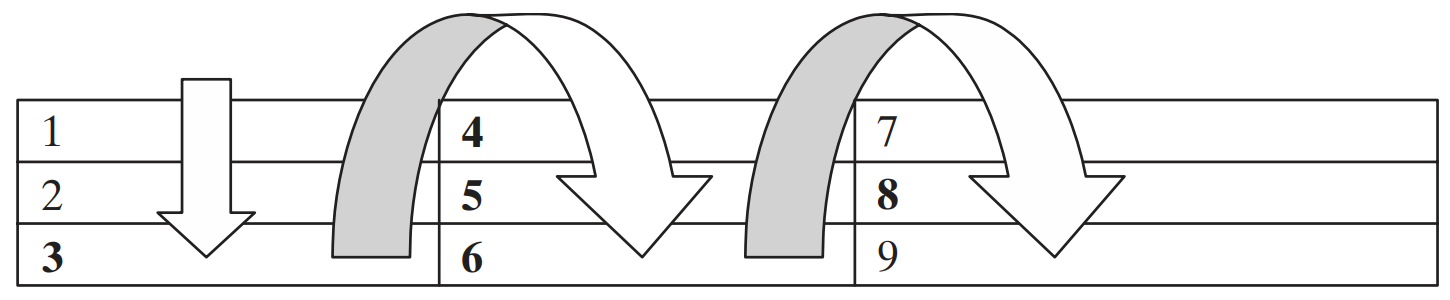

*Tomado de MATLAB para Ingenieros de Holly Moore*.

En la figura 1 podemos observar los índices sencillos de una matriz. Es así como funciona el transformar una matriz a un vector `A(:)`: apilar las columnas una debajo de otra de derecha a izquierda.

Analicemos la misma matriz anterior con sus índices sencillos:


$$A=\left\lbrack \begin{array}{ccc}
4_1  & 8_4  & 0_7 \\
9_2  & 2_5  & 1_8 \\
7_3  & 5_6  & 6_9 
\end{array}\right\rbrack$$


Con esta indexación únicamente podemos extraer:

- Elementos únicos.

- Vectores fila de elementos indicando los índices sencillos.

- Vectores fila de elementos utilizando el operador dos puntos.

Además que también es posible utilizar la palabra reservada `end` como con la anterior indexación.

% Crear la matriz.
A = [4 8 0
     9 2 1
     7 5 6];

% Indexar un único elemento.
A(1)

ans = 4

% Indexar un único elemento.
A(8)

ans = 1

% Indexar un vector de elementos mediante índices sencillos.
A([1 5 9])

ans = 1×3
     4     2     6


% Indexar un vector de elementos mediante el operador dos puntos.
A(4:6)

ans = 1×3
     8     2     5


#### Relación entre la indexación sencilla y la indexación por posición

#### Funciones `ind2sub` y `sub2ind`

En ocasiones quizá necesitemos convertir los índices sencillos a índices por posición (o subíndices), o viceversa. Con este fin podemos utilizar las funciones `ind2sub` (índice a subíndice) o `sub2ind` (subíndice a índice).

Notemos que la salida de la función `ind2sub` son dos variables, `row` y `col`. Por el momento entendamos que en la variable `row` se guardará el número de fila y en la variable `col` se guardará el número de columna.

Además, observemos también que estamos utilizando una función llamada `size`. Esta función permite conocer las dimensiones de un arreglo.

**Índice a subíndice**

**Figura 2.** Conversión de índices a subíndices.

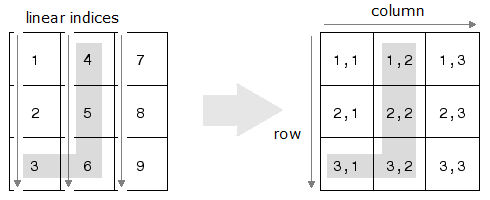

*Tomado de *[*MathWorks: *`ind2sub`](https://www.mathworks.com/help/matlab/ref/ind2sub.html).

**Subíndice a índice**

**Figura 3.** Conversión de subíndices a índices.

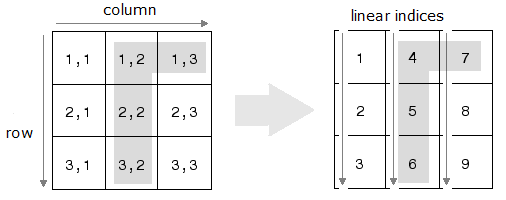

*Tomado de *[*MathWorks: *`sub2ind`](https://www.mathworks.com/help/matlab/ref/sub2ind.html).

Veámoslo con un ejemplo. Sea la matriz con la que hemos venido trabajando:


$$A=\left\lbrack \begin{array}{ccc}
4_{1,1}  & 8_{1,2}  & 0_{1,3} \\
9_{2,1}  & 2_{2,2}  & 1_{2,3} \\
7_{3,1}  & 5_{3,2}  & 6_{3,3} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
4_1  & 8_4  & 0_7 \\
9_2  & 2_5  & 1_8 \\
7_3  & 5_6  & 6_9 
\end{array}\right\rbrack$$


Notemos que se encuentran ambas indexaciones en cada matriz, donde los elementos son los mismos, únicamente varían los índices: en la matriz izquierda se encuentran los índices por posición (o subíndices) y en la matriz de la derecha se encuentran los índices sencillos.

% Crear la matriz.
A = [4 8 0
     9 2 1
     7 5 6];

% Subíndices.
subRow = 1;
subCol = 3;

% Índice sencillo.
idx = 6;

% Aplicación de función sub2ind.
sub2ind(size(A), subRow, subCol)

ans = 7

% Aplicación de función ind2sub.
[row, col] = ind2sub(size(A), idx)

row = 3

col = 2

### Indexación lógica

El uso de valores lógicos es otra forma útil de indexar matrices, especialmente cuando se trabaja con declaraciones condicionales.

Recordemos brevementos los valores lógicos.

true

ans = logical
   1


false

ans = logical
   0


Veámoslo con un ejemplo.

% Crear un vector numérico.
A = [9 7 1 0]

A = 1×4
     9     7     1     0


% Crear un vector lógico.
idx = [true true false false]

idx = 1×4 logical array
   1   1   0   0


% Indexar el vector numérico utilizando el vector lógico.
A(idx)

ans = 1×2
     9     7


Notemos que únicamente se han indexado los elementos correspondientes al `1` lógico. Esta es la indexación lógica.

Además, recordemos que un arreglo lógico se puede obtener a partir de operaciones relacionales.

% Crear un vector numérico.
A = [7 5 6 9 3]

A = 1×5
     7     5     6     9     3


% Crear el vector lógico a partir de una operación relacional.
idx = A >= 7

idx = 1×5 logical array
   1   0   0   1   0


% Indexar el vector numérico utilizando el vector lógico.
A(idx)

ans = 1×2
     7     9


### Relación entre los 3 tipos de indexaciones

Existe una función extremadamente poderosa para determinar índices sencillos, índices por posición y los elementos de éstos índices. Además que se puede utilizar una condición lógica para facilitar búsquedas.

#### Función `find`

La función `find` permite determinar índices y valores de elementos distintos de cero. Aunque su potencial va más allá de esto.

Analicemos el uso de la función `find` únicamente con elementos diferentes de cero.

% Crear un vector numérico.
A = [7 5 6 9 3]

A = 1×5
     7     5     6     9     3


% Obtener índices sencillos de elementos diferentes de 0.
find(A)

ans = 1×5
     1     2     3     4     5


% Obtener índices sencillos de los n primeros elementos diferentes de 0.
find(A, 2)

ans = 1×2
     1     2


% Obtener índices por posición de elementos diferentes de 0.
[row01, col01] = find(A)

row01 = 1×5
     1     1     1     1     1


col01 = 1×5
     1     2     3     4     5


% Obtener índices por posición y elementos diferentes de 0.
[row02, col02, elements01] = find(A)

row02 = 1×5
     1     1     1     1     1


col02 = 1×5
     1     2     3     4     5


elements01 = 1×5
     7     5     6     9     3


Ahora analicemos el potencial extra de la función `find`.

% Obtener índices sencillos de elementos que cumplan la condición.
find(A >= 7)

ans = 1×2
     1     4


% Obtener índices sencillos de los n primeros elementos que cumplan la condición.
find(A >= 7, 1)

ans = 1

% Obtener índices por posición de elementos que cumplan la condición.
[row03, col03] = find(A >= 7)

row03 = 1×2
     1     1


col03 = 1×2
     1     4


### Reemplazar elementos de una matriz

Utilizando cualquier tipo de indexación se puede reemplazar elementos de una matriz. Únicamente se indexan los elementos y se asignan los nuevos valores.

% Crear una vector.
B = 1:5

B = 1×5
     1     2     3     4     5


% Reemplazar un elemento de una matriz.
B(3) = 10

B = 1×5
     1     2    10     4     5


Esto funciona tanto para reemplazar un único elemento o varios elementos. Lo que se debe considerar es que la matriz que se indexa debe ser del mismo tamaño (tener las mismas dimensiones) que la matriz que reemplazará a la matriz indexada.

B(1:2) = [0 0]

B = 1×5
     0     0    10     4     5


### Expandir una matriz

Una forma de expandir una matriz es concatenarla con otros elementos o matrices. No obstante, mediante indexación también es posible expandir una matriz.

Se debe indicar un índice fuera de rango de la matriz, es decir, que sea más grande que las dimensiones de la matriz y asignarle un valor o valores. Esto forzará a la matriz a expandirse rellenando los elementos en las posiciones que no se hayan asignado nada con ceros.

Lo que siempre se debe tener en cuenta es que la matriz resultante siempre debe ser consistente dimensionalmente hablando.

% Crear un vector.
D = [1 2]

D = 1×2
     1     2


% Forzar la expansión del vector con indexación sencilla.
D(5) = 10

D = 1×5
     1     2     0     0    10


% Forzar la expansión del vector con indexación por posición.
D(2, 1) = 0

D = 2×5
     1     2     0     0    10
     0     0     0     0     0


¿Cuál sería la matriz resultante del siguiente código?

### Eliminar elementos de una matriz

Para eliminar elementos de una matriz se utiliza la matriz vacía `[]`. Basta con utilizar cualquier indexación e indexar los elementos que se desean eliminar y asignarles la matriz vacía.

% Crear una vector.
A = 1:5

A = 1×5
     1     2     3     4     5


% Eliminar un elemento de un vector.
A(3) = []

A = 1×4
     1     2     4     5


Esto funciona tanto para eliminar un único elemento o varios elementos. Lo que se debe considerar es que la matriz final debe ser consistente en sus dimensiones.

% Crear una matriz.
C = [1 2 3
     4 5 6]

C = 2×3
     1     2     3
     4     5     6


% Eliminar una fila del vector.
C(2, :) = []

C = 1×3
     1     2     3


¿Cuál sería la matriz resultante del siguiente código?

## Material adicional

- [Creación, concatenación y expansión de matrices](https://www.mathworks.com/help/matlab/math/creating-and-concatenating-matrices.html)

- [Redimensionar y reorganizar matrices](https://www.mathworks.com/help/matlab/math/reshaping-and-rearranging-arrays.html)

- [Crear arreglos de cadenas](https://www.mathworks.com/help/matlab/matlab_prog/create-string-arrays.html)

- [Operaciones lógicas (o booleanas)](https://www.mathworks.com/help/matlab/logical-operations.html)

- [Indexación de arreglos](https://www.mathworks.com/help/matlab/math/array-indexing.html)

- [Encontrar elementos de una matriz que cumplan una condición](https://www.mathworks.com/help/matlab/matlab_prog/find-array-elements-that-meet-a-condition.html)

- [Función `find`](https://www.mathworks.com/help/matlab/ref/find.html)